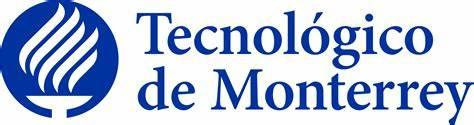

**Actividad 2 análisis de robot lineal 3GDL.**

**Fundamentación de robótica gpo101**

**Hecho por:**

A01736196 | Abraham Ortiz Castro

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*23 de febrero del 2024.*

## Explicación de código.

Debido a que la mayoria del código ha sido explicada en la actividad anterior, solamente se explicará lo nuevo.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

En este caso se pone uno en vez de cero porque ya se trata de una junra prismática

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Para la primera aritulación se ha tomado en cuenta que el eje x ya se encuentra posicionado en la base del robot, por lo tanto para que se pueda ir a la segunda articulación requiere rotar 90 grados negativos sobre el eje y1, por lo tanto me refiero que será de x a z, quedando el eje z ahora viendo hacia arriba. Hablando de la translación se está moviendo en z según el marco de referencia actual y se está moviendo l1, por lo tanto se pone l1 en z solamente y en x y y no se está contando ningún movimiento.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [0  0 -1 ;
           0  1  0;
           1  0  0];

Para el segundo caso, se tiene que z está viendo hacia arriba, x hacia afuera y y hacia adentro del plano, por lo tanto lo que se requiere para que z quede como referencia a l3 se requiere mover sobre el eje x -90 grados, por lo tanto debe de ir de z a y. Así se tendrá la referencia de z en l3. Hablando de la translación, según el sistema de referencia actual se está moviendo l3 en el eje de y, de la misma manera l2 en el eje z, por lo tanto se agregan así y en x se le ponde cero.

%Posición de la articulación 2 respecto a 0
P(:,:,2)= [0 ; l3; l2];
%Matriz de rotación de la junta 2 respecto a 0.... -90 x2 
R(:,:,2)= [1  0   0;
           0  0   1;
           0  -1  0];

Hablando de la última matriz, ya no se requiere agregar ninguna translación ni rotación por lo tanto se le pone cero en la translación y en la rotación la matriz unidad.

P(:,:,3)= [0 ; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,3)= [1  0  0 ;
           0  1  0;
           0  0  1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(RO_inv(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1, l3(t) |
|                 |
| 0, -1, 0,   0   |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0,   0   \
|                |
| 0, 0, 1, l3(t) |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 1, 0,   0   \
|                |
| 0, 0, 1, l3(t) |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /




%Calculamos la matriz de transformación del marco de referencia inercial
%visto desde el actuador final
% disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma manual'));
% RF_O=RO_inv(:,:,GDL);
% PF_O=-RF_O*PO(:,:,GDL);
% TF_O= simplify([RF_O PF_O; Vector_Zeros 1]);
% pretty(TF_O);   

%disp(strcat('Matriz de Transformación T', GDL_str,'_O calculada de forma auntomática'));
%pretty(simplify(inv(T(:,:,GDL))));
%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



Al final los resultados son lógicos, en primera porque en la velocidad angular en todos los ejes son cero, algo que queda muy obvio debido a que sólo existen desplazamientos. Hablando de la velocidad lineal tiene sentido debido a que se están incluyendo en la matriz los tres brazos respecto al tiempo, algo que tiene sentido debido a que los tres pueden moverse y así se espera un buen análisis para el movimiento en todos los brazos.

En conclusión los resultados son lógicos, debido a que incluyen todos los movimientos esperados.